# Løsning til 2017 eksamen

## Opgave 1

## Opgave 2

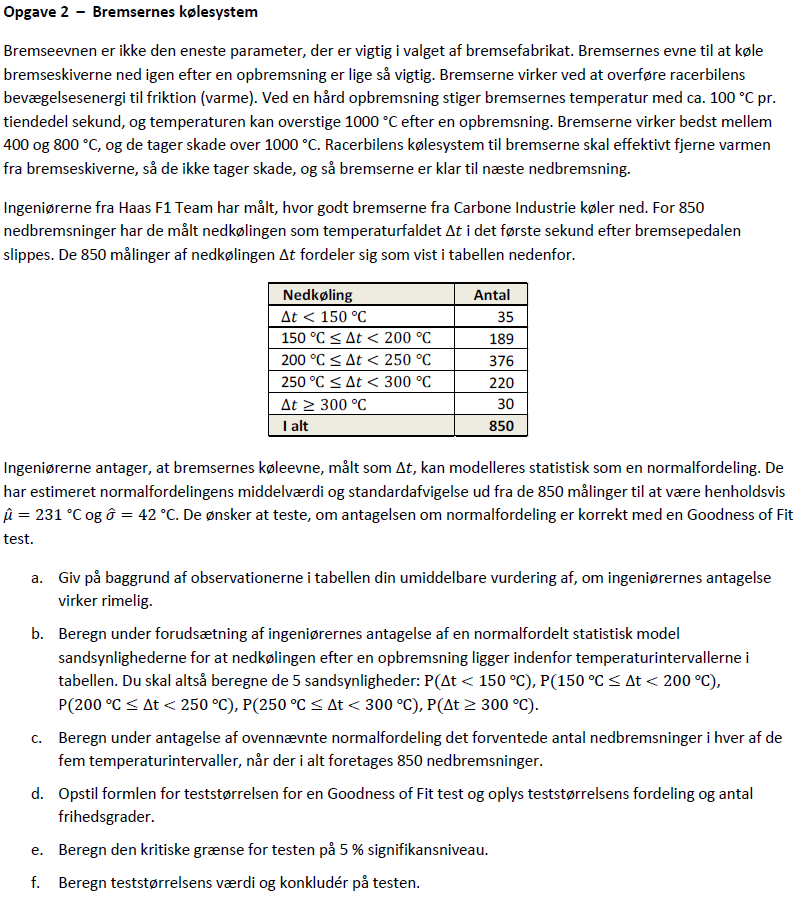

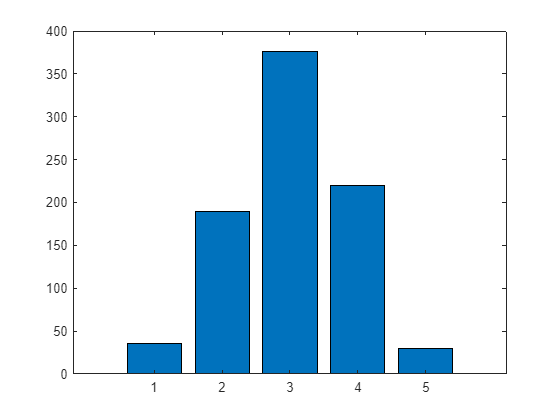

clc; clear;

% Opgave a

% Data fra opgaven
sigma = 42;
mu = 231;


% Antal observeringer i tabellen
obs = 1:1:5;
delta_ts = [35, 189, 376, 220, 30];

% Bar plot og dist plot
figure;
bar(obs, delta_ts);

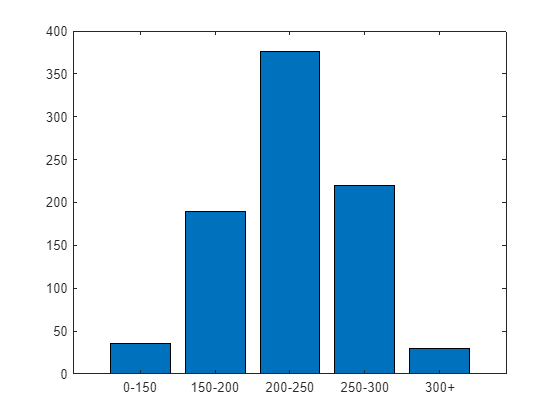


X = categorical({'0-150','150-200','200-250','250-300', '300+'});
X2 = reordercats(X,{'0-150','150-200','200-250','250-300', '300+'});
Y = delta_ts;
bar(X,Y)


dist = makedist("Normal", "mu",mu, "sigma",sigma);

x = 0:1:400;
int = [-5, 2, 0, 2, 5]

int =     -5     2     0     2     5





pd = pdf(dist,x)

pd =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


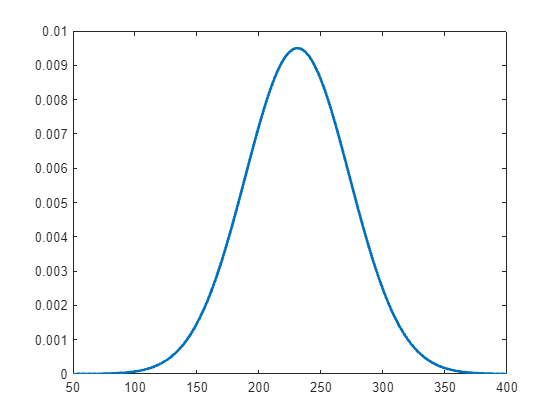


plot(x, pd, 'LineWidth',2), xlim([50, 400])



sort(delta_ts)

ans =     30    35   189   220   376


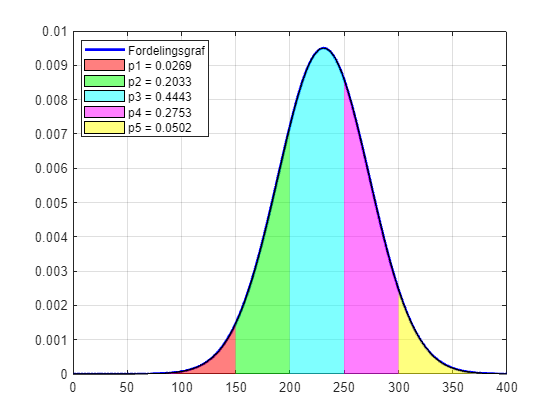

      Interval       Sandsynligheder    I procent
    _____________    _______________    _________

    "-inf -> 150"        0.0269         " 2.69%" 
    "150 til 200"        0.2033         "20.33%" 
    "200 til 250"        0.4443         "44.43%" 
    "250 til 300"        0.2753         "27.53%" 
    "300 -> inf"         0.0502         " 5.02%" 
    "Sum"                     1         "  100%" 



sigma = 42;
mu = 231;

inter = [150,200];
interny = [150,400];


IntervalNormal(mu, sigma, 0, 400, [150,200,250,300])

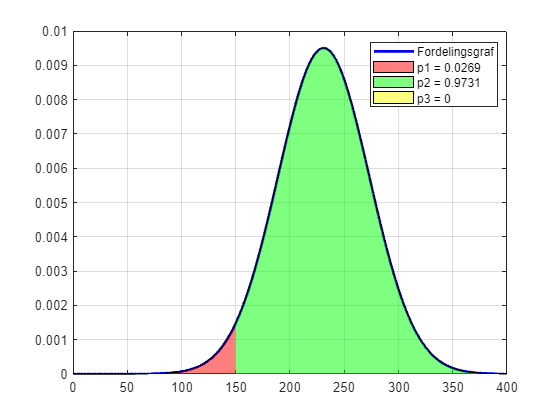

      Interval       Sandsynligheder    I procent
    _____________    _______________    _________

    "-inf -> 150"        0.0269         " 2.69%" 
    "150 til 400"        0.9731         "97.31%" 
    "400 -> inf"              0         "    0%" 
    "Sum"                     1         "  100%" 



IntervalNormal(mu, sigma, 0, 400,interny)




% Opgave b

% Mindre end 150C
p1 = normcdf(150, mu, sigma)

p1 = 0.0269

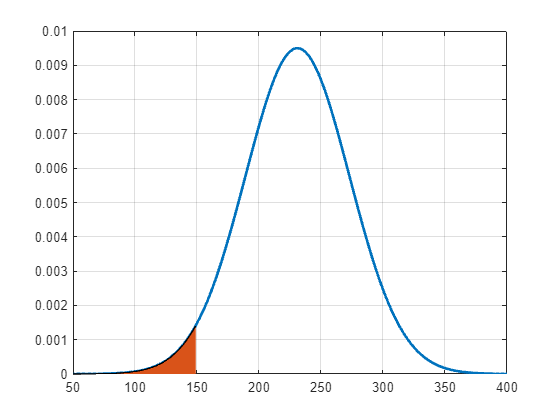



plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 1:150), pd(1, 1:150))
hold off



% Mellem 150 og 200C
p2 = normcdf(200, mu, sigma) - p1

p2 = 0.2033

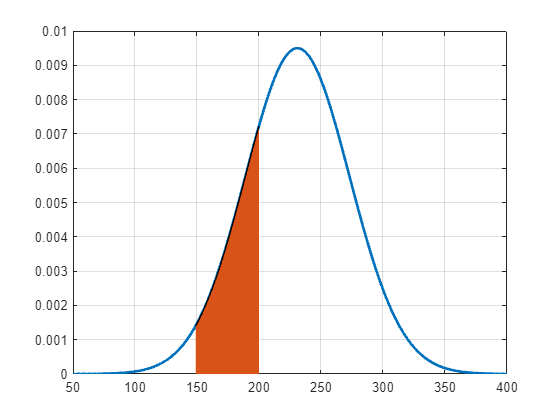


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 150:201), pd(1, 150:201))
hold off


% Mellem 200 og 250C
p3 = normcdf(250, mu, sigma) - normcdf(200, mu, sigma)

p3 = 0.4443

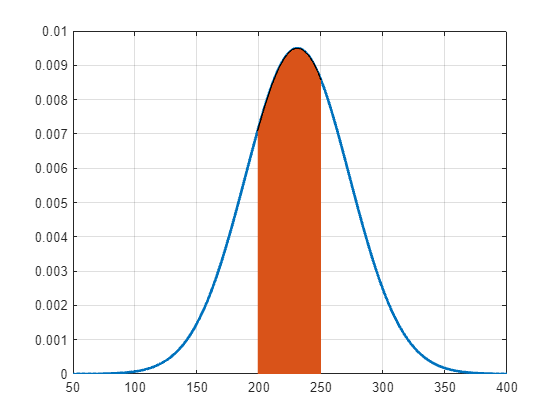

plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 200:251), pd(1, 200:251))
hold off


% Mellem 250 og 300C
p4 = normcdf(300, mu, sigma) - normcdf(250, mu, sigma)

p4 = 0.2753

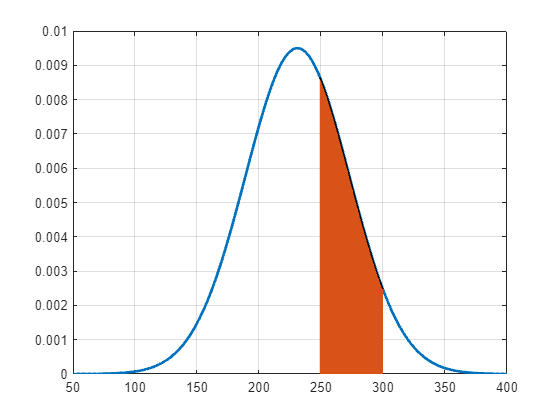


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 250:301), pd(1, 250:301))
hold off



% Mere end 300C
p5 = 1 - normcdf(300, mu, sigma)

p5 = 0.0502

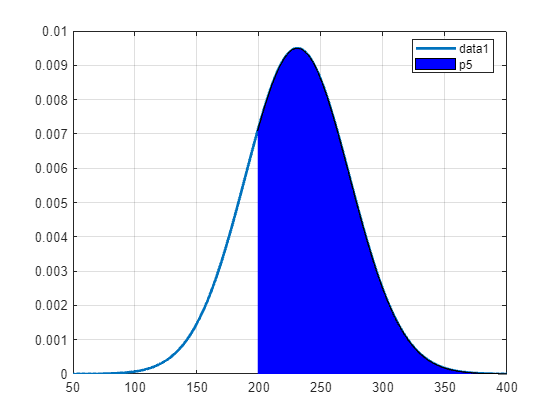


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

aa = area(x(1, inter(end):end), pd(1, inter(end):end), facecolor="b", DisplayName="p5");
legend(Location="best")
hold off

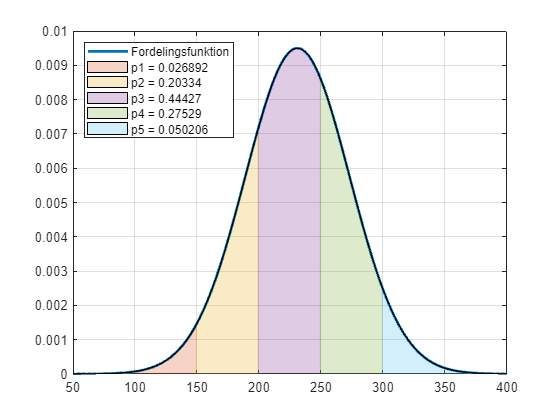


plot(x, pd, 'LineWidth',2, DisplayName="Fordelingsfunktion"), xlim([50, 400]), grid()
hold on
a1 = area(x(1, 1:151), pd(1, 1:151), DisplayName="p1 = " + p1);
a2 = area(x(1, 150:201), pd(1, 150:201), DisplayName="p2 = " + p2);
a3 = area(x(1, 200:251), pd(1, 200:251), DisplayName="p3 = " + p3);
a4 = area(x(1, 250:301), pd(1, 250:301), DisplayName="p4 = " + p4);
a5 = area(x(1, 300:end), pd(1, 300:end), DisplayName="p5 = " + p5);
alpha([a1,a2,a3,a4,a5], 0.25)
legend(Location="northwest")
hold off


x(1, inter(end):end)

ans =    199   200   201   202   203   204   205   206   207   208   209   210   211   212   213   214   215   216   217   218   219   220   221   222   223   224   225   226   227   228   229   230   231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248


% Opgave c
ps = [p1, p2, p3, p4, p5];
n_obs = 850;

forv_obs = ps*n_obs

forv_obs =    22.8582  172.8358  377.6333  233.9974   42.6753




disp(table(delta_ts', ps', forv_obs', VariableNames=["Observerede værdier", "Sandsynligheder", "Forventede værdier"]))

    Observerede værdier    Sandsynligheder    Forventede værdier
    ___________________    _______________    __________________

             35               0.026892              22.858      
            189                0.20334              172.84      
            376                0.44427              377.63      
            220                0.27529                 234      
             30               0.050206              42.675      



% Opgave d
% k er antal observationer
% p er antal parametre - her er er der 2 - middelværdi og afvigelse
obs = delta_ts

obs =     35   189   376   220    30


forv = forv_obs

forv =    22.8582  172.8358  377.6333  233.9974   42.6753



chi2inv(0.95, 2)

ans = 5.9915


sum(((obs-forv).^2)./forv)

ans = 12.5703



chi2_0 = sum(((obs - forv) .^ 2) ./ forv)

chi2_0 = 12.5703


rng default;

pd = makedist("Normal","mu",42,"sigma",231);
x = random(pd, 100, 1);

[h,p,st] = chi2gof(x)

h = 0

p = 0.3775

st = struct with fields:
    chi2stat: 4.2162
          df: 4
       edges: [-638.1296 -336.7818 -186.1078 -35.4339 115.2400 265.9140 416.5879 868.6097]
           O: [5 14 13 25 22 14 7]
           E: [6.4690 10.4995 17.7006 21.9573 20.0432 13.4631 9.8673]


## Opgave 3

clc; clear;



data = xlsread("Data_M4STI1_2017E.xlsx", "K:L")

data =    92.5320   90.2740
   92.8750   95.8780
   94.4790   92.0530
   92.1390   94.2860
   93.7850   89.8920
   93.3090   94.6340
   92.7660   95.8220
   91.9430   95.3620
   92.7160   90.3720
   92.9130   93.9600


data'

ans =    92.5320   92.8750   94.4790   92.1390   93.7850   93.3090   92.7660   91.9430   92.7160   92.9130   91.5310   93.1920   92.1780   92.9060   93.3360   92.0950   92.7120   93.3500   91.1640   94.0360
   90.2740   95.8780   92.0530   94.2860   89.8920   94.6340   95.8220   95.3620   90.3720   93.9600   91.3250   92.0660   91.2900   89.9230   98.2730   92.3700   87.9030   94.8230   92.6470   95.0980



deskripts(data', ["Brembo","Cl"]);

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Brembo"      92.798       0.67258         0.82011             20     
    "Cl"          92.913        6.8375          2.6149             20     




alpha = 0.05;

finv(alpha/2,19,19)

ans = 0.3958

finv(1-alpha/2,19,19)

ans = 2.5265



[h,p,ci,stats]=vartest2(data(:,1), data(:,2),"Alpha",alpha,"Tail","both")

h = 1

p = 5.1338e-06

ci =     0.0389
    0.2485


stats = struct with fields:
    fstat: 0.0984
      df1: 19
      df2: 19




var(data(:,1))/var(data(:,2))

ans = 0.0984

Frihedsgradernes formel


$$\mathrm{df}=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{finv}\,\frac{\frac{1}{20}}{2}\,\mathrm{df}$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}-\delta }{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------


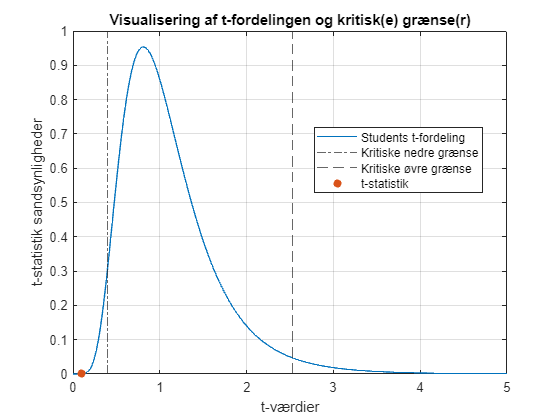

Da h = 1 forkastes nulhypotesen
Ydermere ses det også at t-værdien 0.098366 overstiger den kritiske grænse på 2.5265


ans = struct with fields:
    stats: [1×1 struct]
        p: 5.1338e-06
       ci: [2×1 double]







VarTest2pop(data(:,1), data(:,2),"both", 95, 0)